# Compute the Fundamental Natural Frequency (resonance) of a Plate

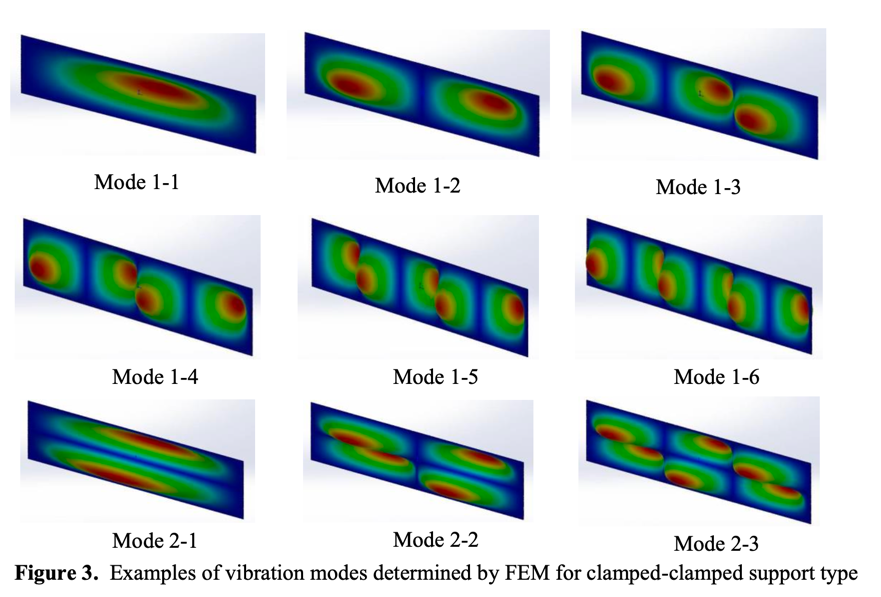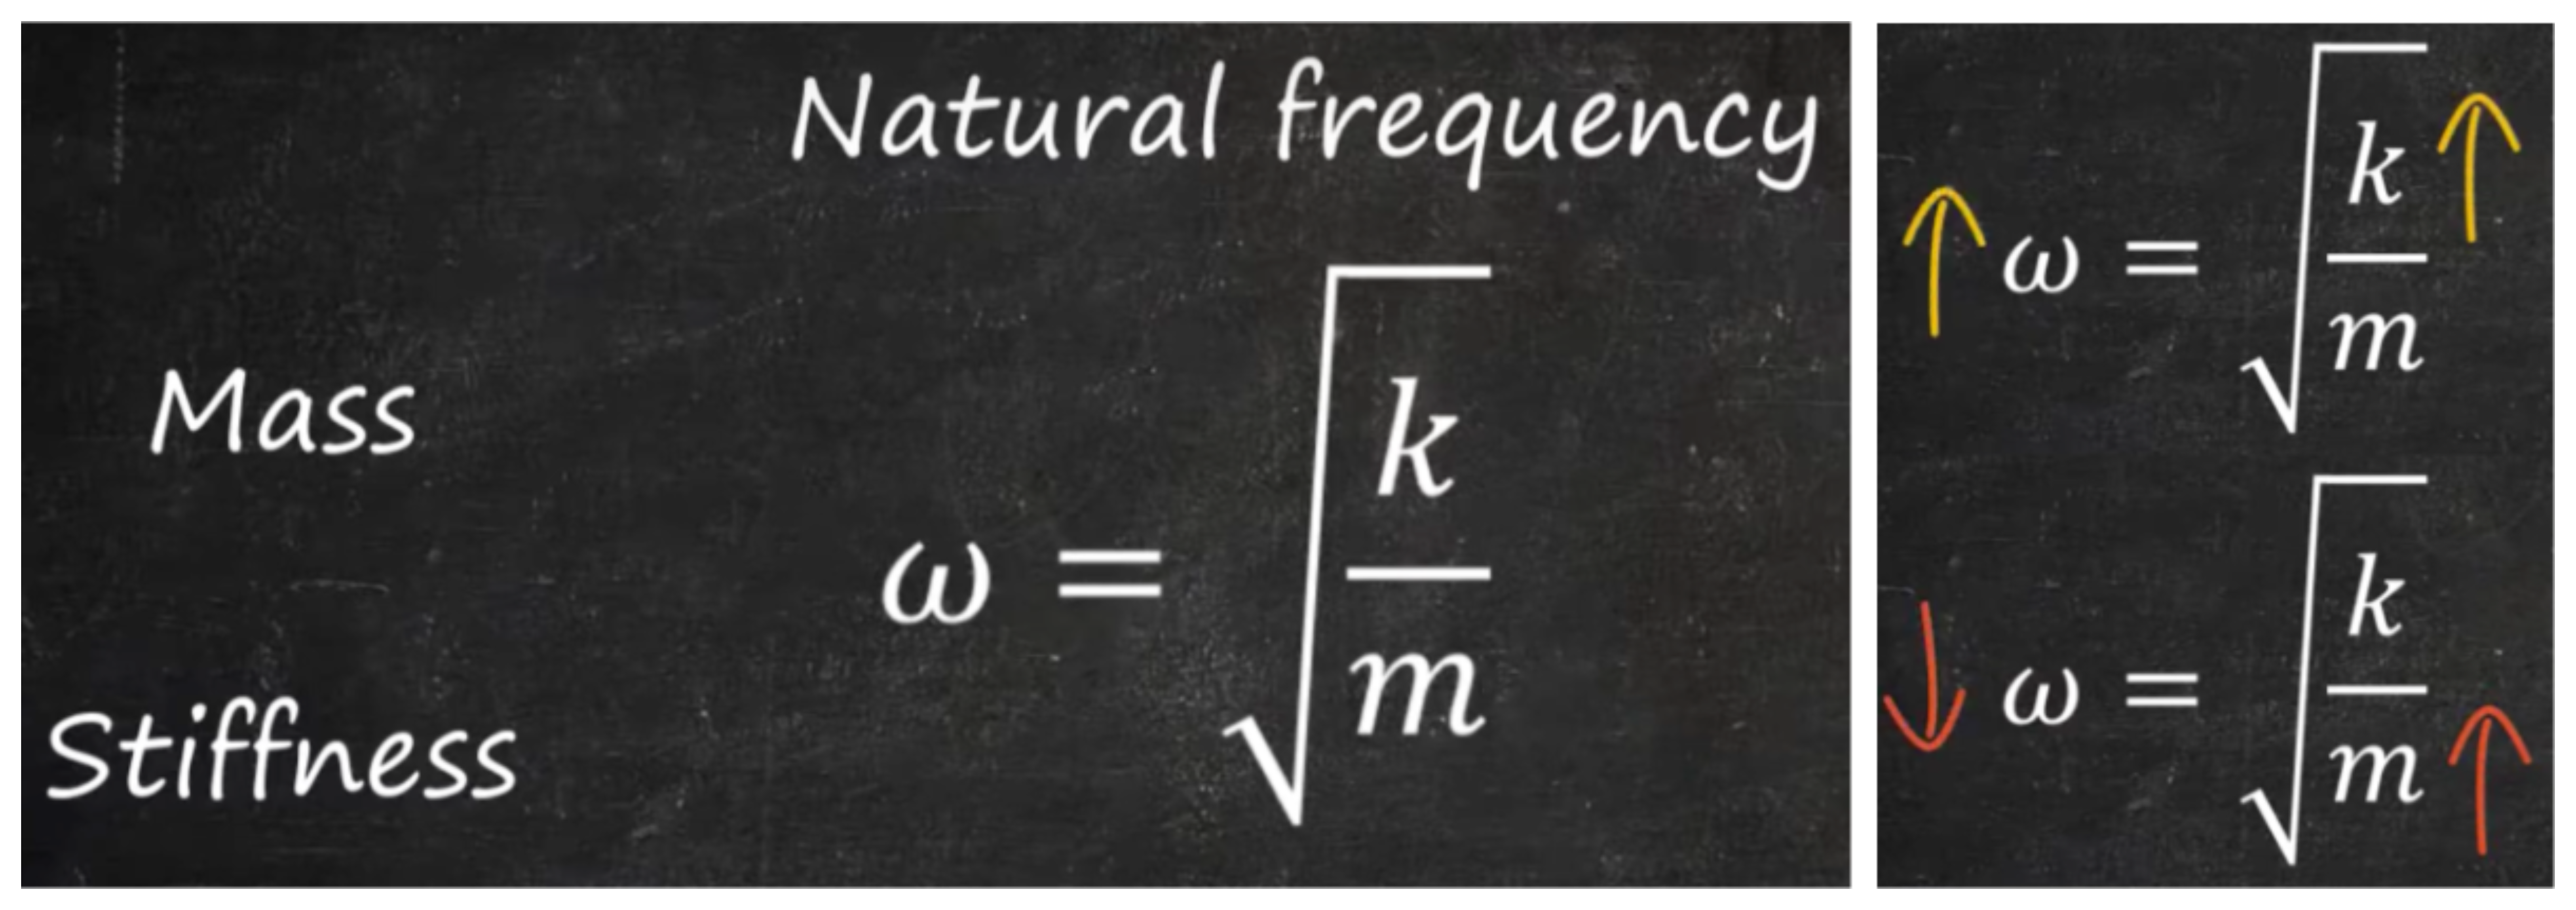

## Matlab Startup File

This m-File code prepare the enviroment to provide access to auxilliary files and sub-folders.

clear; clc; close all;
format short eng                              
[ProjectFolder,AuxFcn_GS] = AuxFcn_Matlab_Startup_File_001; % Project Startup Folder & Graphical Settings

## Method #1 

source: "Medium-scale experiments on vented hydrogen deflagration" Kuznetsov, et. al. (2015)

### Aluminum Plate

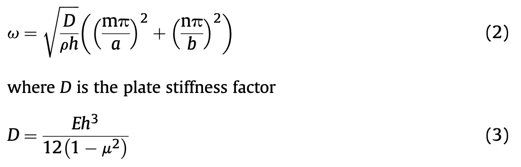

% Given Data
a = 1;        % Plate length in meters
b = 1;        % Plate width in meters
h = 0.010;     % Plate thickness in meters (10 mm)

% Material Properties for Aluminum
E = 70e9;     % Young's modulus in Pascals (N/m^2)
nu = 0.33;    % Poisson's ratio
rho = 2700;   % Density in kg/m^3

% Compute the bending stiffness D
D = (E * h^3) / (12 * (1 - nu^2));
% Compute sqrt(D / (rho * h))
sqrt_D_rhoh = sqrt(D / (rho * h));

% Mode numbers (fundamental mode for clamped plate)
m = 1;
n = 1;
% Compute the fundamental natural frequency
omega = sqrt_D_rhoh * ((m*pi/a)^2+(n*pi/b)^2);

% Display result
fprintf('Fundamental Natural Frequency of the Aluminum Plate (Simply Supported): %.2f Hz\n', omega);

Fundamental Natural Frequency of the Aluminum Plate (Simply Supported): 307.36 Hz


fprintf('This results it might be wrong becasue it is not [Hz] but [rad/s]');

This results it might be wrong becasue it is not [Hz] but [rad/s]

fprintf('The correct frequency should be: %.2f Hz\n', omega/(2*pi));

The correct frequency should be: 48.92 Hz


### Plexiglas (PMMA) Plate

% Given Data
a = 1;        % Plate length in meters
b = 1;        % Plate width in meters
h = 0.020;     % Plate thickness in meters (20 mm)

% Material Properties for Plexiglas (Acrylic, PMMA)
E = 2.8e9;    % Young's modulus in Pascals (N/m^2) (2.8 GPa)
nu = 0.35;    % Poisson's ratio (dimensionless)
rho = 1190;   % Density in kg/m^3

% Compute the bending stiffness D
D = (E * h^3) / (12 * (1 - nu^2));
% Compute sqrt(D / (rho * h))
sqrt_D_rhoh = sqrt(D / (rho * h));

% Mode numbers (fundamental mode for clamped plate)
i = 1;
j = 1;
% Compute the fundamental natural frequency
omega = sqrt_D_rhoh * ((i*pi/a)^2+(j*pi/b)^2);

% Display result
fprintf('Fundamental Natural Frequency of the Plexiglas Plate (Simply Supported): %.2f Hz\n', omega);

Fundamental Natural Frequency of the Plexiglas Plate (Simply Supported): 186.62 Hz


fprintf('This results it might be wrong becasue it is not [Hz] but [rad/s]');

This results it might be wrong becasue it is not [Hz] but [rad/s]

fprintf('The correct frequency should be: %.2f Hz\n', omega/(2*pi));

The correct frequency should be: 29.70 Hz


### Steel Plate

% Given Data
a = 0.900;        % Plate length in meters
b = 0.900;        % Plate width in meters
h = 0.010;     % Plate thickness in meters (10 mm)

% Material Properties for Aluminum
E = 205e9;     % Young's modulus in Pascals (N/m^2)
nu = 0.3;    % Poisson's ratio
rho = 7850;   % Density in kg/m^3

% Compute the bending stiffness D
D = (E * h^3) / (12 * (1 - nu^2));

% Compute sqrt(D / (rho * h))
sqrt_D_rhoh = sqrt(D / (rho * h));

% Mode numbers (fundamental mode for clamped plate)
i = 1;
j = 1;
% Compute the fundamental natural frequency
omega = sqrt_D_rhoh * ((i*pi/a)^2+(j*pi/b)^2);
% Display result
fprintf('Fundamental Natural Frequency of the Steel Plate (Simply Supported): %.2f Hz\n', omega);

Fundamental Natural Frequency of the Steel Plate (Simply Supported): 376.86 Hz


fprintf('This results it might be wrong becasue it not [Hz] but [rad/s]');

This results it might be wrong becasue it not [Hz] but [rad/s]

fprintf('The correct frequency should be: %.2f Hz\n', omega/(2*pi));

The correct frequency should be: 59.98 Hz


## Method #2

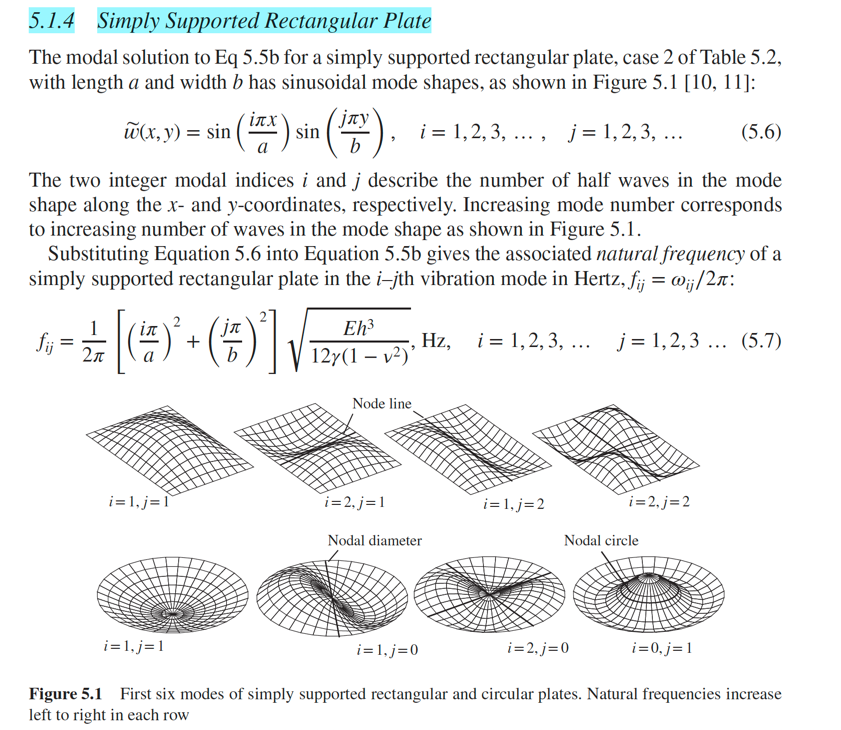

### Aluminum Plate

% Given Data
a = 1;        % Plate length in meters
b = 1;        % Plate width in meters
h = 0.010;     % Plate thickness in meters (10 mm)

% Material Properties for Aluminum
E = 70e9;     % Young's modulus in Pascals (N/m^2)
nu = 0.33;    % Poisson's ratio
rho = 2700;   % Density in kg/m^3
gamma = h * rho;

% Mode numbers (fundamental mode for clamped plate)
i = 1;
j = 1;
% Compute the fundamental natural frequency
f_simplySupportedPlate = (1/(2 * pi)) * ((i * pi / a)^2+(j * pi / b)^2) * ((E * h^3)/(12 * gamma * (1 - nu^2)))^0.5;
fprintf('Fundamental Natural Frequency of the Aluminum Plate: %.2f Hz\n', f_simplySupportedPlate);

Fundamental Natural Frequency of the Aluminum Plate: 48.92 Hz


### Plexiglas Plate

% Given Data
a = 1;        % Plate length in meters
b = 1;        % Plate width in meters
h = 0.020;     % Plate thickness in meters (20 mm)

% Material Properties for Plexiglas (Acrylic, PMMA)
E = 2.8e9;    % Young's modulus in Pascals (N/m^2) (2.8 GPa)
nu = 0.35;    % Poisson's ratio (dimensionless)
rho = 1190;   % Density in kg/m^3
gamma = h * rho;

% Mode numbers (fundamental mode for clamped plate)
i = 1;
j = 1;
% Compute the fundamental natural frequency
f_simplySupportedPlate = (1/(2 * pi)) * ((i * pi / a)^2+(j * pi / b)^2) * ((E * h^3)/(12 * gamma * (1 - nu^2)))^0.5;
fprintf('Fundamental Natural Frequency of the PMMA Plate: %.2f Hz\n', f_simplySupportedPlate);

Fundamental Natural Frequency of the PMMA Plate: 29.70 Hz


## Method #3

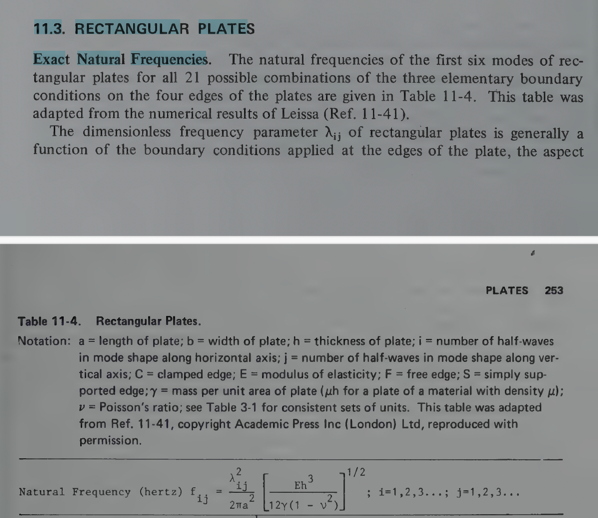

### Aluminum Plate

% Given Data
a = 1;        % Plate length in meters
b = 1;        % Plate width in meters
h = 0.010;     % Plate thickness in meters (10 mm)

% Material Properties for Aluminum
E = 70e9;     % Young's modulus in Pascals (N/m^2)
nu = 0.33;    % Poisson's ratio
rho = 2700;   % Density in kg/m^3
gamma = h * rho;

% Compute the fundamental natural frequency
f_ij = @(lambda_ij) (lambda_ij / (2 * pi * a^2)) * ((E * h^3) / (12 * gamma * (1 - nu^2)))^0.5;

#### Boundary Conditions (BCs) #3

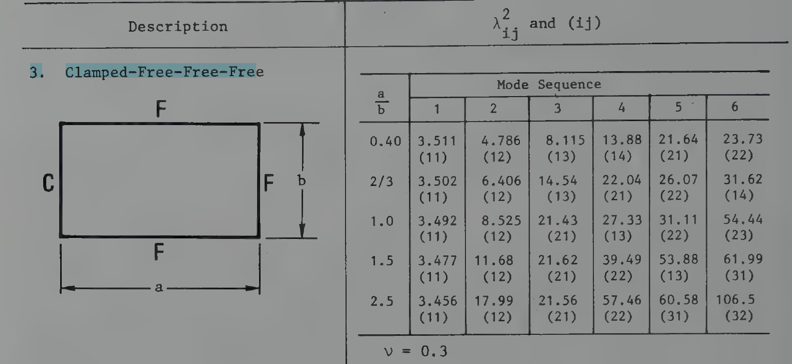

lambda_BCs3 = 3.492;
f_BCs3 = f_ij(lambda_BCs3);
fprintf('Fundamental Natural Frequency of the Aluminum Plate (BCs: Clamped-Free-Free-Free): %.2f Hz\n', f_BCs3);

Fundamental Natural Frequency of the Aluminum Plate (BCs: Clamped-Free-Free-Free): 8.65 Hz


#### Boundary Conditions (BCs) #6

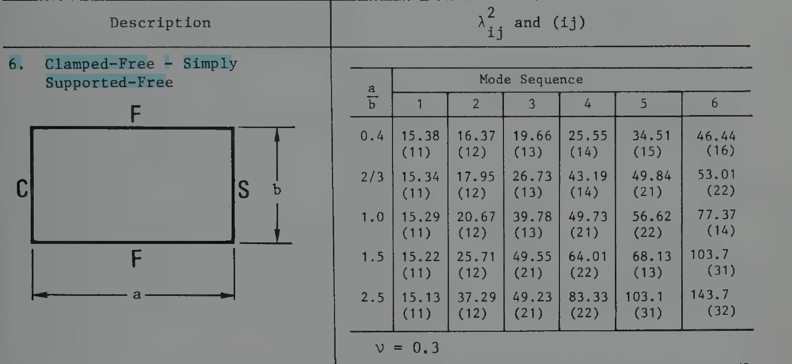

lambda_BCs6 = 15.29;
f_BCs6 = f_ij(lambda_BCs6);
fprintf('Fundamental Natural Frequency of the Aluminum Plate (BCs: Clamped-Free-Simply Supported-Free): %.2f Hz\n', f_BCs6);

Fundamental Natural Frequency of the Aluminum Plate (BCs: Clamped-Free-Simply Supported-Free): 37.89 Hz


#### Boundary Conditions (BCs) #8

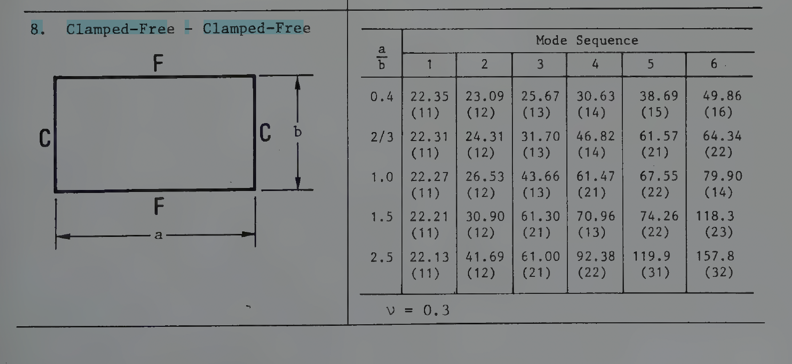

lambda_BCs8 = 22.27;
f_BCs8 = f_ij(lambda_BCs8);
fprintf('Fundamental Natural Frequency of the Aluminum Plate (BCs: Clamped-Free-Clamped-Free): %.2f Hz\n', f_BCs8);

Fundamental Natural Frequency of the Aluminum Plate (BCs: Clamped-Free-Clamped-Free): 55.19 Hz


#### Boundary Conditions (BCs) #16

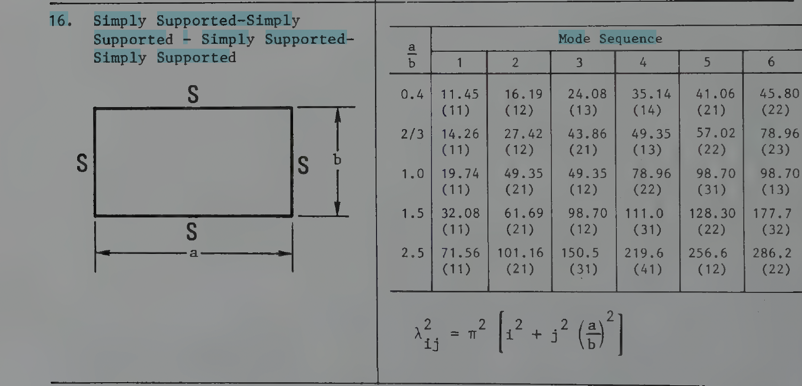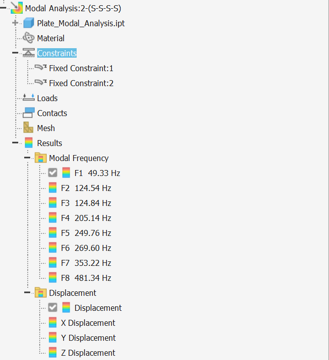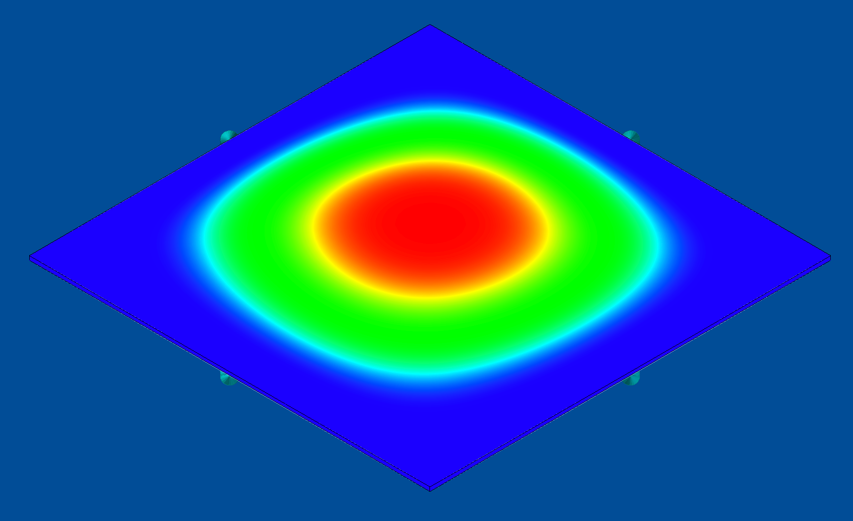

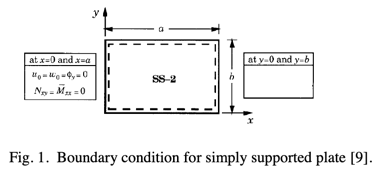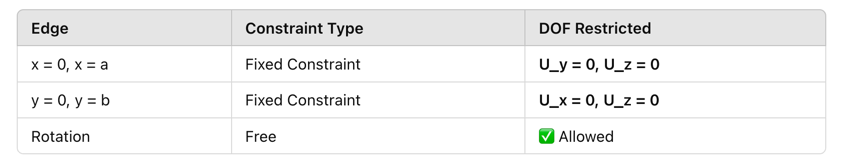

lambda_BCs16 = 19.74;
f_BCs16 = f_ij(lambda_BCs16);
fprintf('Fundamental Natural Frequency of the Aluminum Plate (BCs: Simply Supported-Simply Supported-Simply Supported-Simply Supported): %.2f Hz\n', f_BCs16);

Fundamental Natural Frequency of the Aluminum Plate (BCs: Simply Supported-Simply Supported-Simply Supported-Simply Supported): 48.92 Hz


#### Boundary Conditions (BCs) #17

Which BCs Should You Use for Your Explosion Chamber?

Since your **bottom plate is fixed to the ground**, and the **side plates are attached but not fully welded**, the **best assumption** for the **side plates** is:

✅ **Simply Supported on Three Edges & Clamped on One (S-S-S-C).**

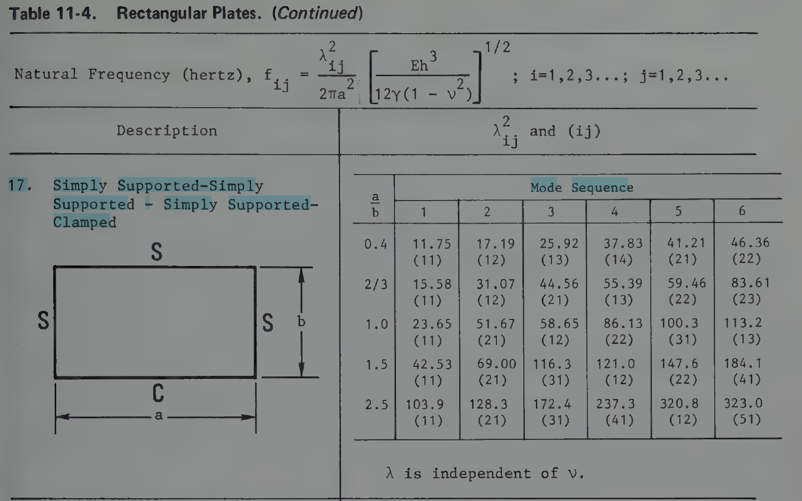

lambda_BCs17 = 23.65;
f_BCs17 = f_ij(lambda_BCs17);
fprintf('Fundamental Natural Frequency of the Aluminum Plate (BCs: Simply Supported-Simply Supported-Simply Supported-Clamped): %.2f Hz\n', f_BCs17);

Fundamental Natural Frequency of the Aluminum Plate (BCs: Simply Supported-Simply Supported-Simply Supported-Clamped): 58.61 Hz


#### Boundary Conditions (BCs) #21

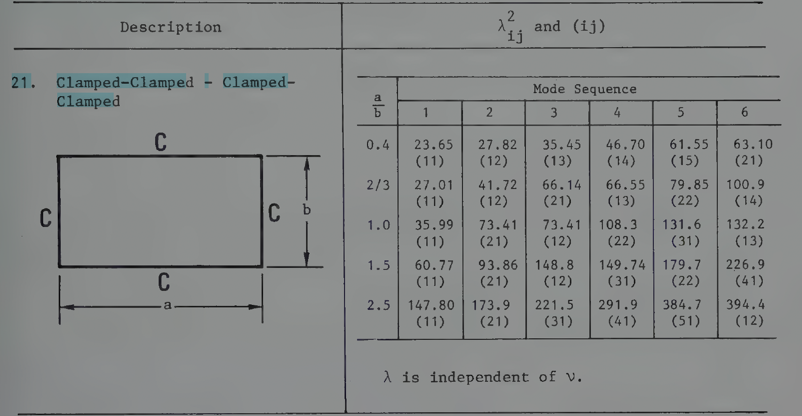 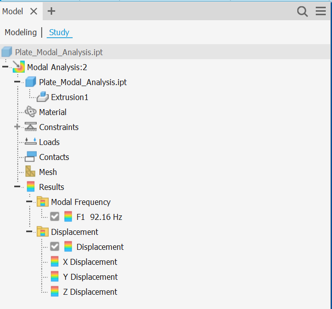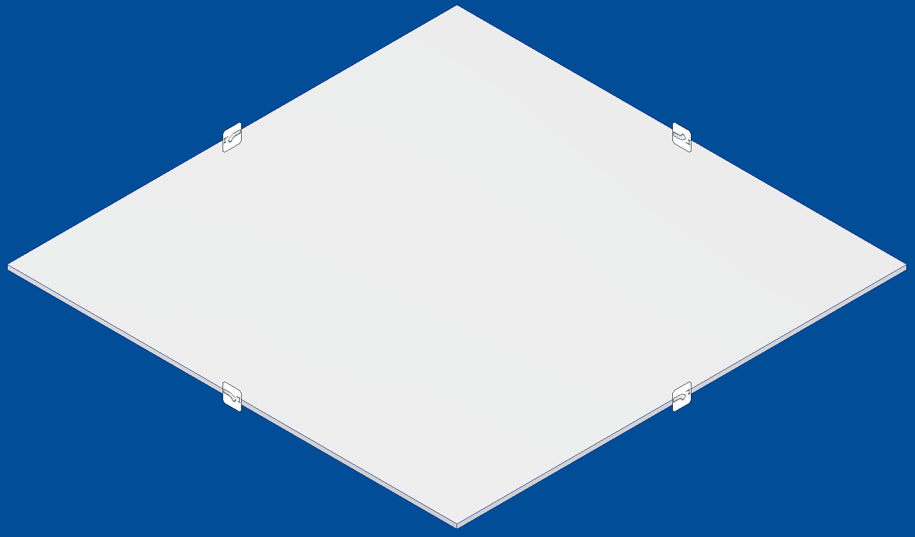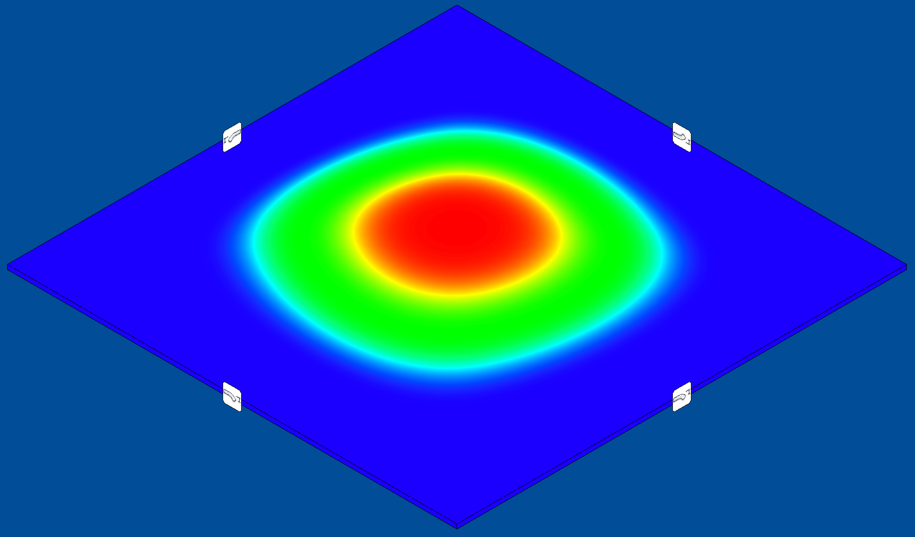

lambda_BCs21 = 35.99; % 1-1
% % lambda_BCs21 = 108.3; % 2-2
% lambda_BCs21 = 131.6; % 3-1

f_BCs21 = f_ij(lambda_BCs21);
fprintf('Fundamental Natural Frequency of the Aluminum Plate (BCs: Clamped-Clamped-Clamped-Clamped): %.2f Hz\n', f_BCs21);

Fundamental Natural Frequency of the Aluminum Plate (BCs: Clamped-Clamped-Clamped-Clamped): 89.19 Hz
